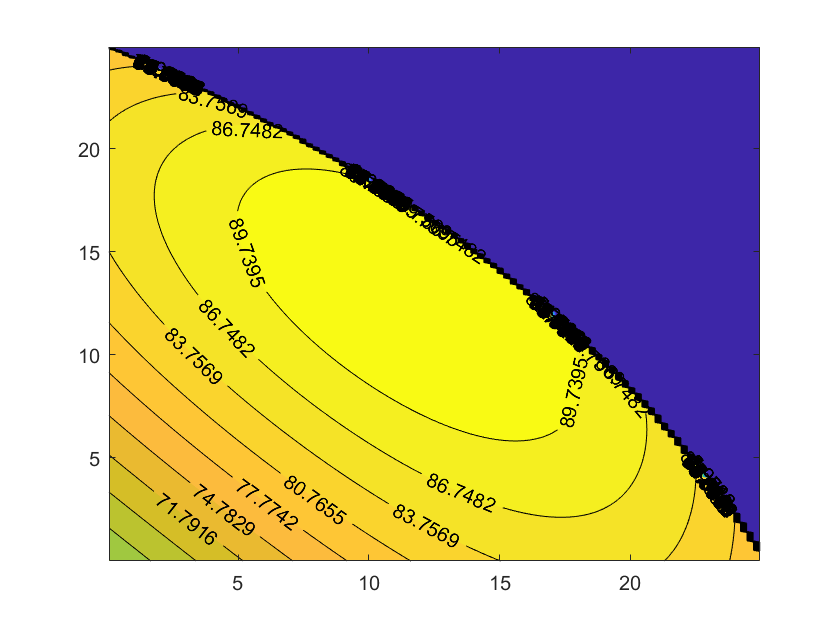

% Live Script per un diffusore piano a doppia rampa (il secondo angolo è riferito rispetto al 
% primo e non all'orizzontale):
% Nella prima parte si vede come varia la predita di pressione in funzione
% dei due angoli di rampa, per un deteriminato numero di Mach.

clear
clc


M = 2.2;    % silder numero di Mach
p1 = 10^5;
T1 = 280;
gamma = 1.4;

theta1 = linspace(0.001,theta_max(M,gamma)-0.02,100);
pi_inlet_vec = [];
    
for j = [1:length(theta1)]
    [p2,T2,M2] = urto_obliquo(theta1(j),p1,T1,M,gamma);
    theta2 = [0.001:0.001:(theta_max(M2,gamma)-0.02)];
    for k = [1:length(theta2)]
                
        [pi_inlet] = Inlet_urto_doppio(theta1(j),theta2(k),p1,T1,M,gamma);
        pi_inlet_vec(k,j) = pi_inlet; 
    
    end
end

n = length(pi_inlet_vec(:,1));

% Grafico con curve isolivello efficienza diffusore %; asse x primo angolo
% di rampa; asse y secondo angolo di rampa; asse z efficienza
contourf(theta1.*180/pi,linspace(0.001,n*(0.001*180/pi),n),pi_inlet_vec*100,30,'ShowText','on')

% Parte 2:
% Questa routine è molto lenta da calcolre, è stato lasciato l'output dell'indice del ciclo per
% verificare il progresso; questo codice calcola, per ogni numero di Mach i
% due angoli ottimali di rampa per ottenere la minor perdita di pressione
% nel diffusore.



clear
clc

M = linspace(1.5,5,30);        % asse numero di Mach

p1 = 10^5;
T1 = 280;
gamma = 1.4;
theta1_opt = [];
theta2_opt = [];
eff_vec= [];

for i = [1:length(M)]
    i  % output per vedere il progresso del ciclo
    theta1 = linspace(0.001,theta_max(M(i),gamma)-0.02,100);
    pi_inlet_vec = [];
    
    for j = [1:length(theta1)]
        [p2,T2,M2] = urto_obliquo(theta1(j),p1,T1,M(i),gamma);
        theta2 = [0.001:0.001:(theta_max(M2,gamma)-0.02)];
        for k = [1:length(theta2)]
                
            [pi_inlet] = Inlet_urto_doppio(theta1(j),theta2(k),p1,T1,M(i),gamma);
            pi_inlet_vec(k,j) = pi_inlet; 
    
        end
    end

      eff_max = max(max(pi_inlet_vec));
      [x,y]=find(pi_inlet_vec==eff_max);
      theta1_opt(i) = theta1(y)*180/pi;
      theta2_opt(i) = x*0.001*180/pi;
      eff_vec(i) = eff_max;
end

i =      1


i =      2


i =      3


i =      4


i =      5


i =      6


i =      7


i =      8


i =      9


i =     10


i =     11


i =     12


i =     13


i =     14


i =     15


i =     16


i =     17


i =     18


i =     19


i =     20


i =     21


i =     22


i =     23


i =     24


i =     25


i =     26


i =     27


i =     28


i =     29


i =     30


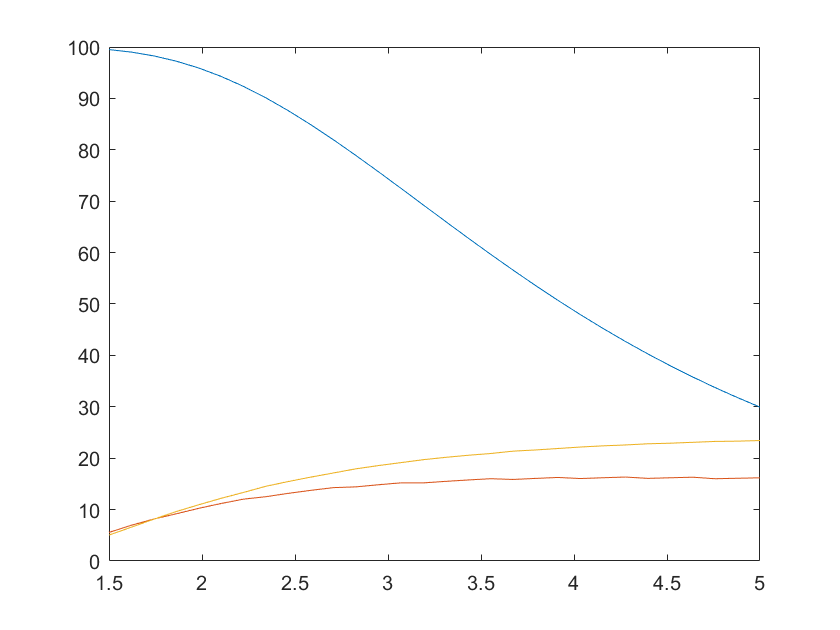

% grafico efficienza, angoli di rampa: asse x numero di Mach; asse y     
% efficienza % e angoli in gradi. Curva decrescente efficienza, cuve
% crescenti angoli (a Mach elevato il secondo angolo è maggiore del primo)
plot(M,eff_vec*100)
hold on 
plot(M,theta1_opt)
plot(M,theta2_opt)
hold off